#  Geometric Integration of Quaternions

cf. Andrle, Michael S., & Crassidis, John L. “Geometric Integration of Quaternions.” Journal of Guidance, Control, and Dynamics, vol. 36, no. 6, 2013, pp. 1762-67.

clc
clear


format long
global MOI


## parameters and initial condition

MOI = diag([200 200 100]); % Moment of inertia

dt = 10;
tspan = 0:dt:4*60*60;
xIni = [0;0;0;1; 0.05; 0; 0.01]; % paper


## Runge–Kutta method

xRK = ode4(@eulerEom, tspan, xIni);


## adaptive ODE solver

[~, xAdaptive] = ode45(@eulerEom, tspan, xIni);


## Crouch–Grossman method

### three-stage CG3 mixed-scheme

n = 3; % n-stage CG method
[a, b, c] = butcherTable(3, 'CG')

a =                    0                   0                   0
   0.750000000000000                   0                   0
   0.550925925925926   0.157407407407407                   0


b =    0.254901960784314
  -0.666666666666667
   1.411764705882353


c =                    0
   0.750000000000000
   0.708333333333333



k = zeros(n, n);
K = zeros(4,4,n);
w = zeros(n,3); %

w(1,:) = xIni(5:7) % intermidiate angular rate

w =    0.050000000000000                   0   0.010000000000000
                   0                   0                   0
                   0                   0                   0


wOut = zeros(length(tspan),3); % nx3
wOut(1,:) = w(1,:);
qOut = zeros(length(tspan), 4); % nx4
qOut(1,:) = xIni(1:4);

for jj = 1:length(tspan)-1

    % for each stage
    w(1,:) = wOut(jj,:);
    tmpk = -MOI^(-1) * cross(w(1,:)', MOI * w(1,:)');
    k(1,:) = tmpk';

    tmpw = w(1,:);
    for s = 1:n        
        for j = 1:s-1  % s = 1のときは入らない
            tmpw = tmpw + a(s,j) * dt .* k(j,:);
        end
        w(s,:) = tmpw;

        tmp = -MOI^(-1) * cross(w(s,:)', MOI * w(s,:)');
        k(s,:) = tmp';
        K(:,:,s) = 0.5 * qMultMat(4, 1,[w(s,:), 0]); % 4x4xs

    end

    tmp = zeros(1,3);
    for i =1:n
        tmp = tmp + dt .* b(i) .* k(i,:);
    end
    wOut(jj+1,:) = wOut(jj,:) + tmp;

    tmp = expm(dt * b(1) * K(:,:,1));
    for i = 2:n
        tmp = expm(dt .* b(i) .* K(:,:,i)) * tmp;
    end

    tmpQ = tmp * qOut(jj,:)';
    qOut(jj+1,:) = tmpQ';

end


## five-stage CG4

n = 5; % n-stage CG method
[a, b, c] = butcherTable(4, 'CG')

a =                    0                   0                   0                   0                   0
   0.817722798812485                   0                   0                   0                   0
   0.319987637547643   0.065986426355602                   0                   0                   0
   0.921441719446495   0.499785777677357  -1.096998444837158                   0                   0
   0.355235855902332   0.239095837230733   1.391856572420325  -1.109297939211356                   0


b =    0.137083152063076
  -0.018369853156402
   0.739781398537078
  -0.190714256550589
   0.332219559106837


c =                    0
   0.817722798812485
   0.385974063903245
   0.324229052286694
   0.876890326342043



k = zeros(n, 3);
K = zeros(4,4,n);
w = zeros(n,3); %

w(1,:) = xIni(5:7) % intermidiate angular rate

w =    0.050000000000000                   0   0.010000000000000
                   0                   0                   0
                   0                   0                   0
                   0                   0                   0
                   0                   0                   0


wOut = zeros(length(tspan),3); % nx3
wOut(1,:) = w(1,:);
qOutCG4 = zeros(length(tspan), 4); % nx4
qOutCG4(1,:) = xIni(1:4);

for jj = 1:length(tspan)-1

    % for each stage
    w(1,:) = wOut(jj,:);
    tmpk = -MOI^(-1) * cross(w(1,:)', MOI * w(1,:)');
    k(1,:) = tmpk';

    tmpw = w(1,:);
    for s = 1:n        
        for j = 1:s-1  % s = 1のときは入らない
            tmpw = tmpw + a(s,j) * dt .* k(j,:);
        end
        w(s,:) = tmpw;

        tmp = -MOI^(-1) * cross(w(s,:)', MOI * w(s,:)');
        k(s,:) = tmp';
        K(:,:,s) = 0.5 * qMultMat(4, 1,[w(s,:), 0]); % 4x4xs

    end

    tmp = zeros(1,3);
    for i =1:n
        tmp = tmp + dt .* b(i) .* k(i,:);
    end
    wOut(jj+1,:) = wOut(jj,:) + tmp;

    tmp = expm(dt * b(1) * K(:,:,1));
    for i = 2:n
        tmp = expm(dt .* b(i) .* K(:,:,i)) * tmp;
    end

    tmpQ = tmp * qOutCG4(jj,:)';
    qOutCG4(jj+1,:) = tmpQ';

end

## analytical solutions (closed form solution, CS)

w1 = xIni(5);
w2 = xIni(6);
w3 = xIni(7);
wn = w3 * (MOI(2,2) - MOI(3,3)) / MOI(2,2);
wCS = [w1.*cos(wn.*tspan(:))+w2*sin(wn.*tspan(:)) w2.*cos(wn.*tspan(:))-w1*sin(wn.*tspan(:)) w3.*ones(length(tspan),1)];


## data handling and comparison

qAd = xAdaptive(:,1:4);
wAd = xAdaptive(:,5:7);
qRK = xRK(:,1:4);
wRK = xRK(:,5:7);

% quaternion norm
figure
plot(tspan./60/60, log10(1 - vecnorm(qRK,2,2).^2)); hold on
plot(tspan./60/60, log10(1 - vecnorm(qOut,2,2).^2),'o')

plot(tspan./60/60, log10(1 - vecnorm(qOutCG4,2,2).^2),'x')

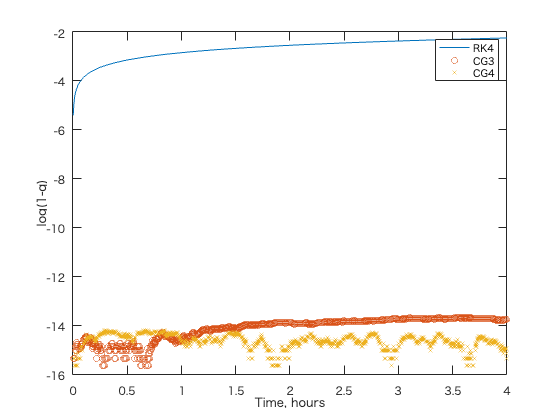

xlabel('Time, hours')
ylabel('log(1-q)')
legend('RK4', 'CG3', 'CG4')


% quaternion, adpativeを真値として，，，
qe_RK = qErr(4, qAd, qRK);
qe_CG = qErr(4, qAd, qOut);
